## 1. Load data and initial steps

clc; clear; close all;
%% Load data and initial steps
data = readtable('BikeSharing.csv');

% Variables
vars = {'season','year','holiday','hour','weekday','workingday','weather',...
        'feel_temp','humidity','windspeed'};

X = [];

% Data pre-processing
for i = 1:numel(vars)
    col = data.(vars{i});
    
    % Group hour variable into 3 categories: 0–8, 8–16, 16–24
    if strcmp(vars{i}, 'hour')
        hour_group = zeros(size(col));
        hour_group(col >= 0 & col < 8)  = 1;  % night
        hour_group(col >= 8 & col < 16) = 2;  % daytime
        hour_group(col >= 16 & col <= 23) = 3; % evening
        col = hour_group;
    end

    if iscell(col) || isstring(col)
        col = categorical(col);
        col = double(col);
    end
   
    if islogical(col)
        col = double(col);
    end
    
    X = [X col];
end

% Target Variable
y = data.count;

% Normalization 
X = normalize(X);

## 2. Visualization on 2 Dimension and Deciding on Number of Principal Components

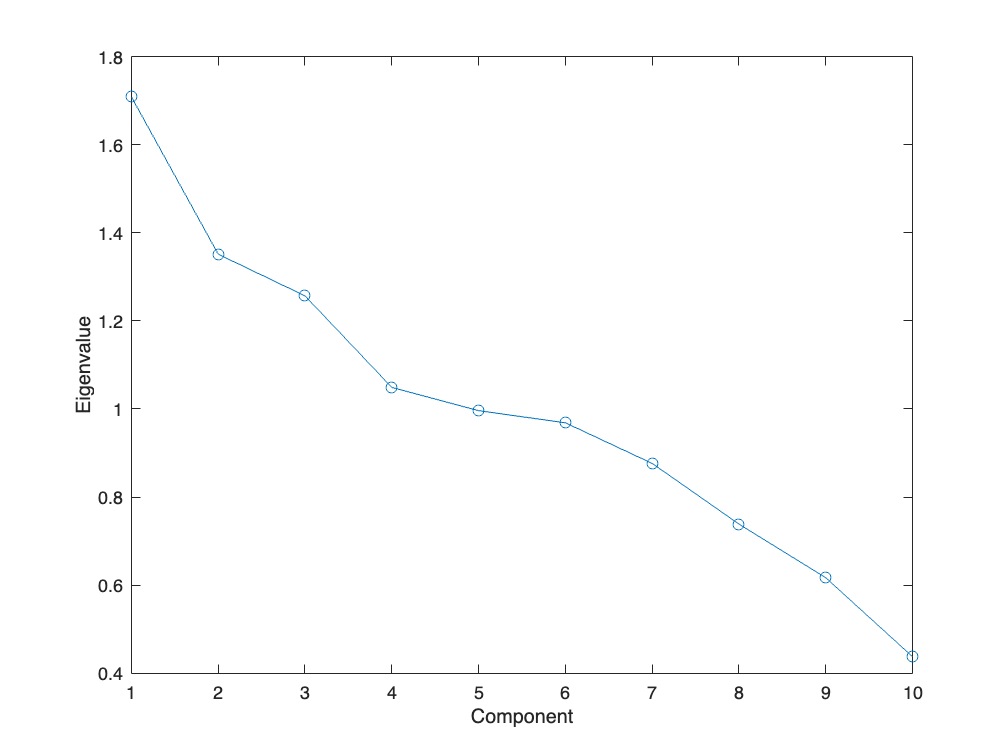

%% PCA
[coeff, score, latent, tsquared, explained] = pca(X);

% Scree Plot
figure;
plot(latent, '-o');
xlabel('Component');
ylabel('Eigenvalue'); exportgraphics(gcf, 'PCA_ScreePlot.png', 'Resolution', 300); 

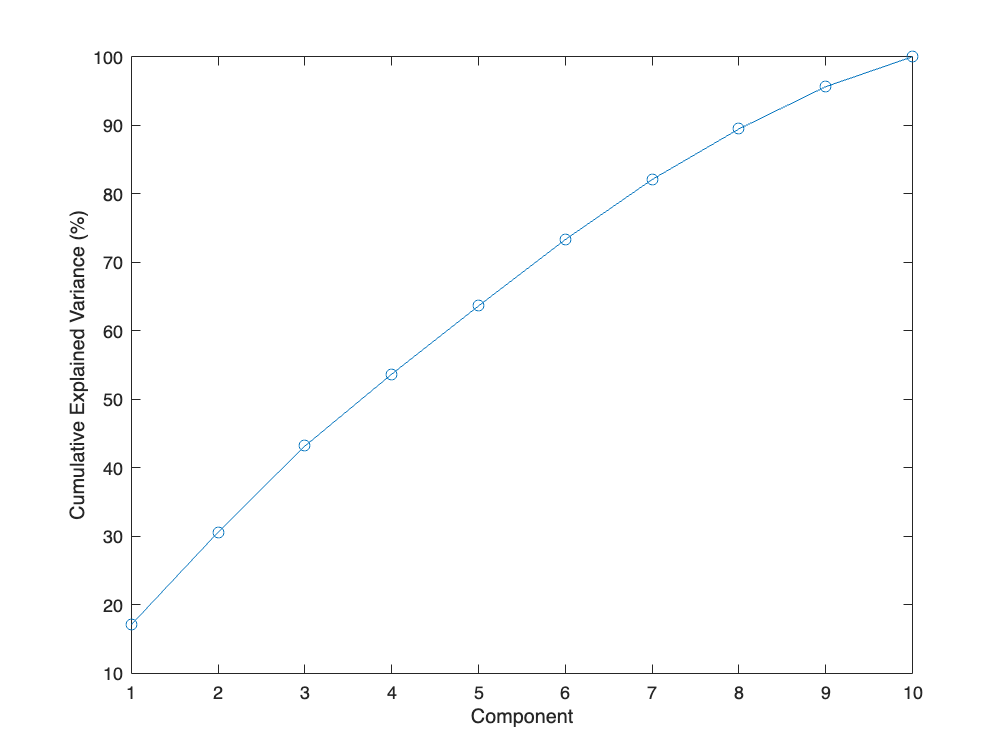

% Cumulative Explained Variance
figure;
plot(cumsum(explained), '-o');
xlabel('Component');
ylabel('Cumulative Explained Variance (%)'); exportgraphics(gcf, 'PCA_CEV.png', 'Resolution', 300);

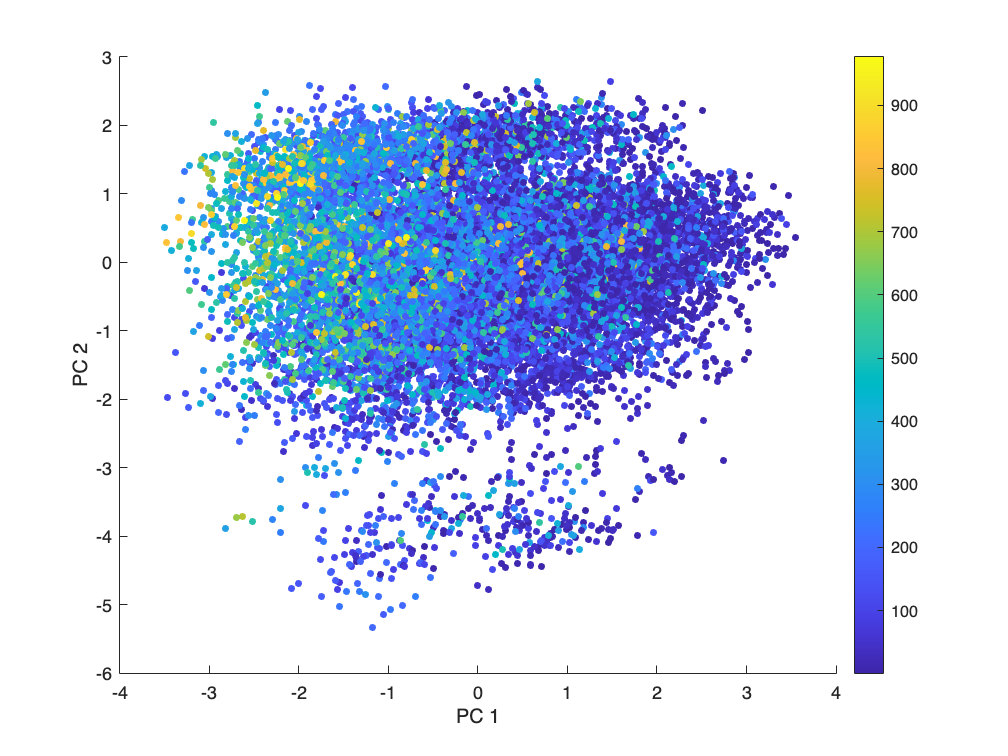

%% PCA 2D Visualization
figure;
scatter(score(:,1), score(:,2), 15, y, 'filled');
xlabel('PC 1');
ylabel('PC 2');
colorbar;
colormap(parula); exportgraphics(gcf, 'PCA_2D.png', 'Resolution', 300);

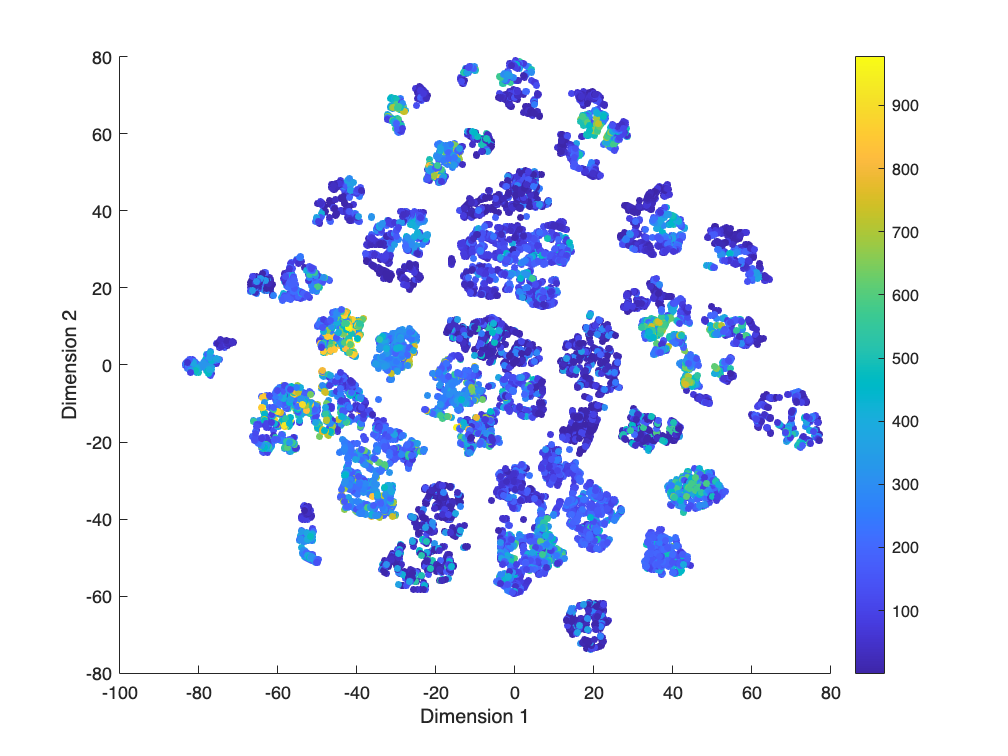

%% t-SNE Visualization 
rng('default');  % reproducibility
% Euclidean distance was used(looking at the results from the models with
% the other distances
[Y, loss] = tsne(X, ...
    'Algorithm', 'barneshut', ...
    'Distance', 'euclidean', ...
    'Perplexity', 50, ...
    'LearnRate', 500);
figure;
scatter(Y(:,1), Y(:,2), 15, y, 'filled');
xlabel('Dimension 1');
ylabel('Dimension 2'); colorbar; colormap(parula); exportgraphics(gcf, 'tSNE_Euclidean.png', 'Resolution', 300);

## 3. Predictive Performance Comparison

%% Predictive Performance Comparison 
% Baseline model
model_base = fitrensemble(X, y, 'Method','Bag');
y_pred_base = predict(model_base, X);
r2_base = corr(y, y_pred_base)^2;
rmse_base = sqrt(mean((y - y_pred_base).^2));

% PCA model
k = 4;  % selected from scree plot
X_pca = score(:,1:k);
model_pca = fitrensemble(X_pca, y, 'Method','Bag');
y_pred_pca = predict(model_pca , X_pca);
r2_pca = corr(y, y_pred_pca)^2;
rmse_pca = sqrt(mean((y - y_pred_pca).^2));

% t-SNE model
model_tsne = fitrensemble(Y, y, 'Method','Bag');
y_pred_tsne = predict(model_tsne, Y);
r2_tsne = corr(y, y_pred_tsne)^2;
rmse_tsne = sqrt(mean((y - y_pred_tsne).^2));
fprintf('Base   : R^2 = %.3f, RMSE = %.2f\n', r2_base, rmse_base);

Base   : R^2 = 0.787, RMSE = 85.35


fprintf('PCA    : R^2 = %.3f, RMSE = %.2f\n', r2_pca, rmse_pca);

PCA    : R^2 = 0.760, RMSE = 95.99


fprintf('t-SNE  : R^2 = %.3f, RMSE = %.2f\n', r2_tsne, rmse_tsne);

t-SNE  : R^2 = 0.795, RMSE = 84.00
